# Predicting True Air Speed from Other Sensors

This example shows how to use historical data to train a regression model that is capable of predicting the True Air Speed (TAS) of a flight from the measurements of other sensors. Such models can be useful in controls applications where it may be desirable to use a regression model as a nonlinear state estimator for a non-observable or costly-to-observe state.  These types of models can also be used as surrogate models in simulations and trade-studies, in cases where a physics-based model is too complex to create or takes too long to simulate.

## Import data from Excel

Start by reading in the data with code generated by the Import Tool. Also remove data recorded when the aircraft was stationary on the ground as that will not be useful for predicting airspeed.

FlightData = importFlightData("FlightData.xlsx");
% perform simple clean up of stationary ground data
FlightData = FlightData(FlightData.TrueAirSpeed >= 10, :);
head(FlightData)

            Time            FuelQuantity    OilPressure    OilTemperature    LatitudePosition    LongitudePosition    Altitude    ExhaustTemperature    FuelFlow    FanSpeed    TrueAirSpeed    WindDirection    WindSpeed
    ____________________    ____________    ___________    ______________    ________________    _________________    ________    __________________    ________    ________    ____________    _____________    _________

    02-Jun-2001 05:50:04       7966.8         90.354           58.805             44.891              -63.508          

## Visualize data

We can see the flight path by viewing a `geoplot` of latitude and longitude.

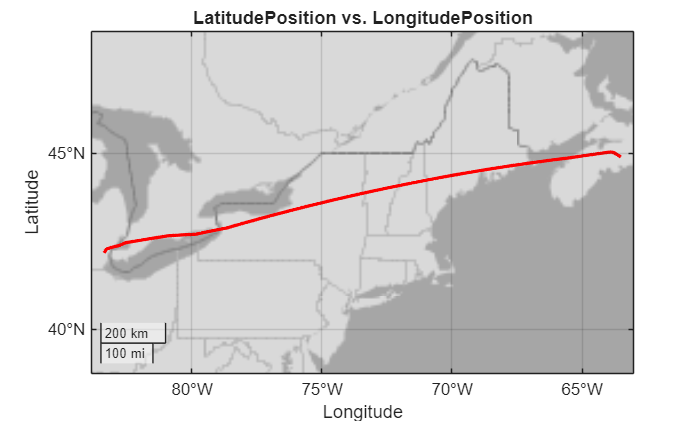

figure
% Specify basemap that doesn't require internet download
geobasemap darkwater
% Create geoplot of FlightData.LatitudePosition and FlightData.LongitudePosition
h = geoplot(FlightData.LatitudePosition,FlightData.LongitudePosition,"LineWidth",2,"Color","red");

% Add title
title("LatitudePosition vs. LongitudePosition")

Some of the sensors appear to have dropouts that we'll need to clean.

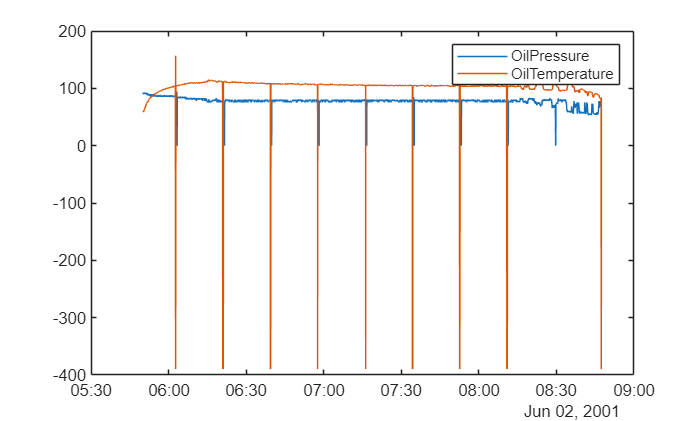

figure
% Create plot of FlightData.Time and FlightData.OilPressure
plot(FlightData.Time,FlightData.OilPressure,"DisplayName","OilPressure");

hold on
% Create plot of FlightData.Time and FlightData.OilTemperature
plot(FlightData.Time,FlightData.OilTemperature,"DisplayName","OilTemperature");
hold off

legend

## Clean sensor data

Use the Data Cleaner to remove the sensor dropouts for oil pressure and temperature.

FlightDataClean = cleanOilSensors(FlightData);


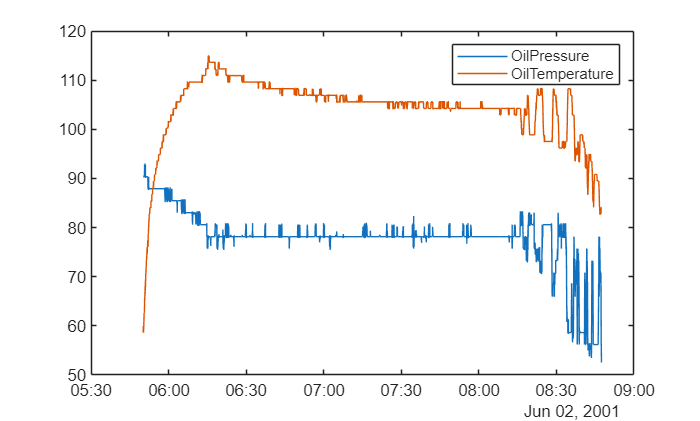

figure
% Create plot of FlightDataClean.Time and FlightDataClean.OilPressure
plot(FlightDataClean.Time,FlightDataClean.OilPressure,"DisplayName","OilPressure");

hold on
% Create plot of FlightDataClean.Time and FlightDataClean.OilTemperature
plot(FlightDataClean.Time,FlightDataClean.OilTemperature,"DisplayName","OilTemperature");
hold off

legend

## Model True Air Speed

We can model TAS with a regression model trained in the Regression Learner app. We'll use a bagged decision tree with default settings, which produces very accurate cross-validated results. Normally in a machine learning workflow we'd use a separate hold-out test set to verify results, but we'll skip that here for brevity.

rng(1) % reproducibility
mdl = trainTASModel(FlightDataClean)

mdl = struct with fields:
            predictFcn: @(x)ensemblePredictFcn(predictorExtractionFcn(x))
     RequiredVariables: {'Altitude'  'ExhaustTemperature'  'FanSpeed'  'FuelFlow'  'FuelQuantity'  'OilPressure'  'OilTemperature'  'WindDirection'  'WindSpeed'}
    RegressionEnsemble: [1×1 classreg.learning.regr.RegressionBaggedEnsemble]
                 About: 'This struct is a trained model exported from Regression Learner R2022a.'
          HowToPredict: 'To make predictions on a new table, T, use: ↵  yfit = c.predictFcn(T) ↵replacing 'c' with the name of the variable that is this struct, e.g. 'trainedModel'. ↵ ↵The table, T, must contain the variables returned by: ↵  c.RequiredVariables ↵Variable formats (e.g. matrix/vector, datatype) must match the original training data. ↵Additional variables are ignored. ↵ ↵For more information, see <a href="matlab:helpview(fullfile(docroot, 'stats', 'stats.map'), 'appregression_exportmodeltoworkspace')">How to predict using an exported model</a

PredictedAirSpeed = mdl.predictFcn(FlightDataClean);


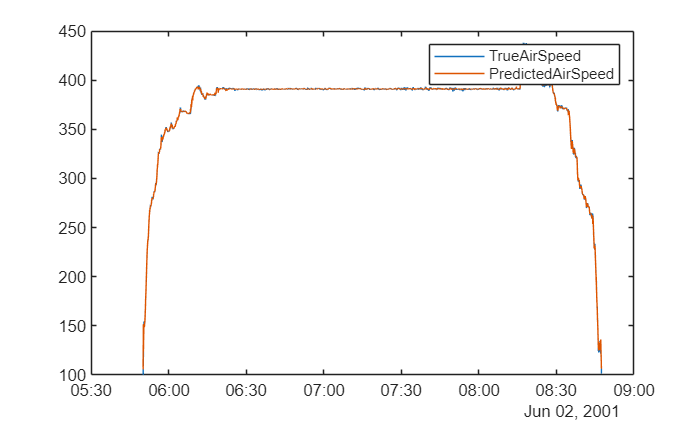

figure
% Create plot of FlightDataClean.Time and FlightDataClean.TrueAirSpeed
plot(FlightDataClean.Time,FlightDataClean.TrueAirSpeed,"DisplayName","TrueAirSpeed");

hold on
% Create plot of FlightDataClean.Time and PredictedAirSpeed
plot(FlightDataClean.Time,PredictedAirSpeed,"DisplayName","PredictedAirSpeed");
hold off

legend

## Predictor importance

Which measurements are important for making predictions? One benefit of the bagged decision tree model is it automatically provides a measure of predictor importance. 

FuelFlow is the most important predictor in this case, followed by WindDirection, WindSpeed, and FanSpeed. 

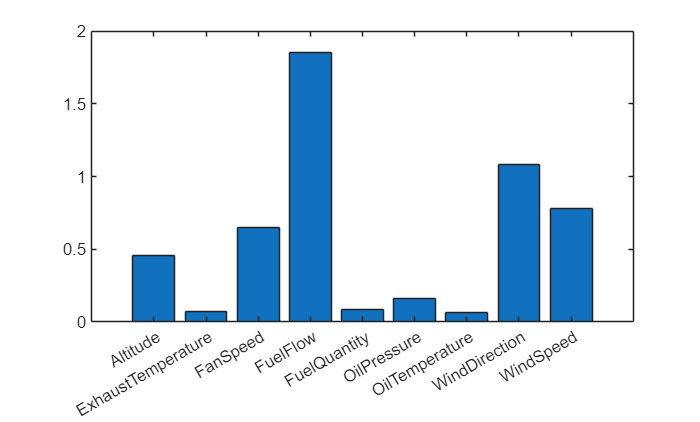

figure
bar(mdl.RegressionEnsemble.predictorImportance)
xticklabels(mdl.RequiredVariables)